# Week 9 Crane Lab (3D Velocity Kinematics)

**Written by:        **Caiden Bonney

**Created:            **3/11/25

**Modified:          ** 3/12/25

**Background:     **

The motion of rigid bodies in 3D space involves rotations and extensions, which can be complex due to their interactions. Using rotating frames of reference simplifies velocity analysis by breaking motion into manageable components. In this lab, we apply 3D kinematics to study a crane’s motion, focusing on velocity equations and rotational transformations.

**Required Files:**

- ME326_05_Activity6_BonneyCaiden_MatLabFile

- Bar.stl

## Task 1:

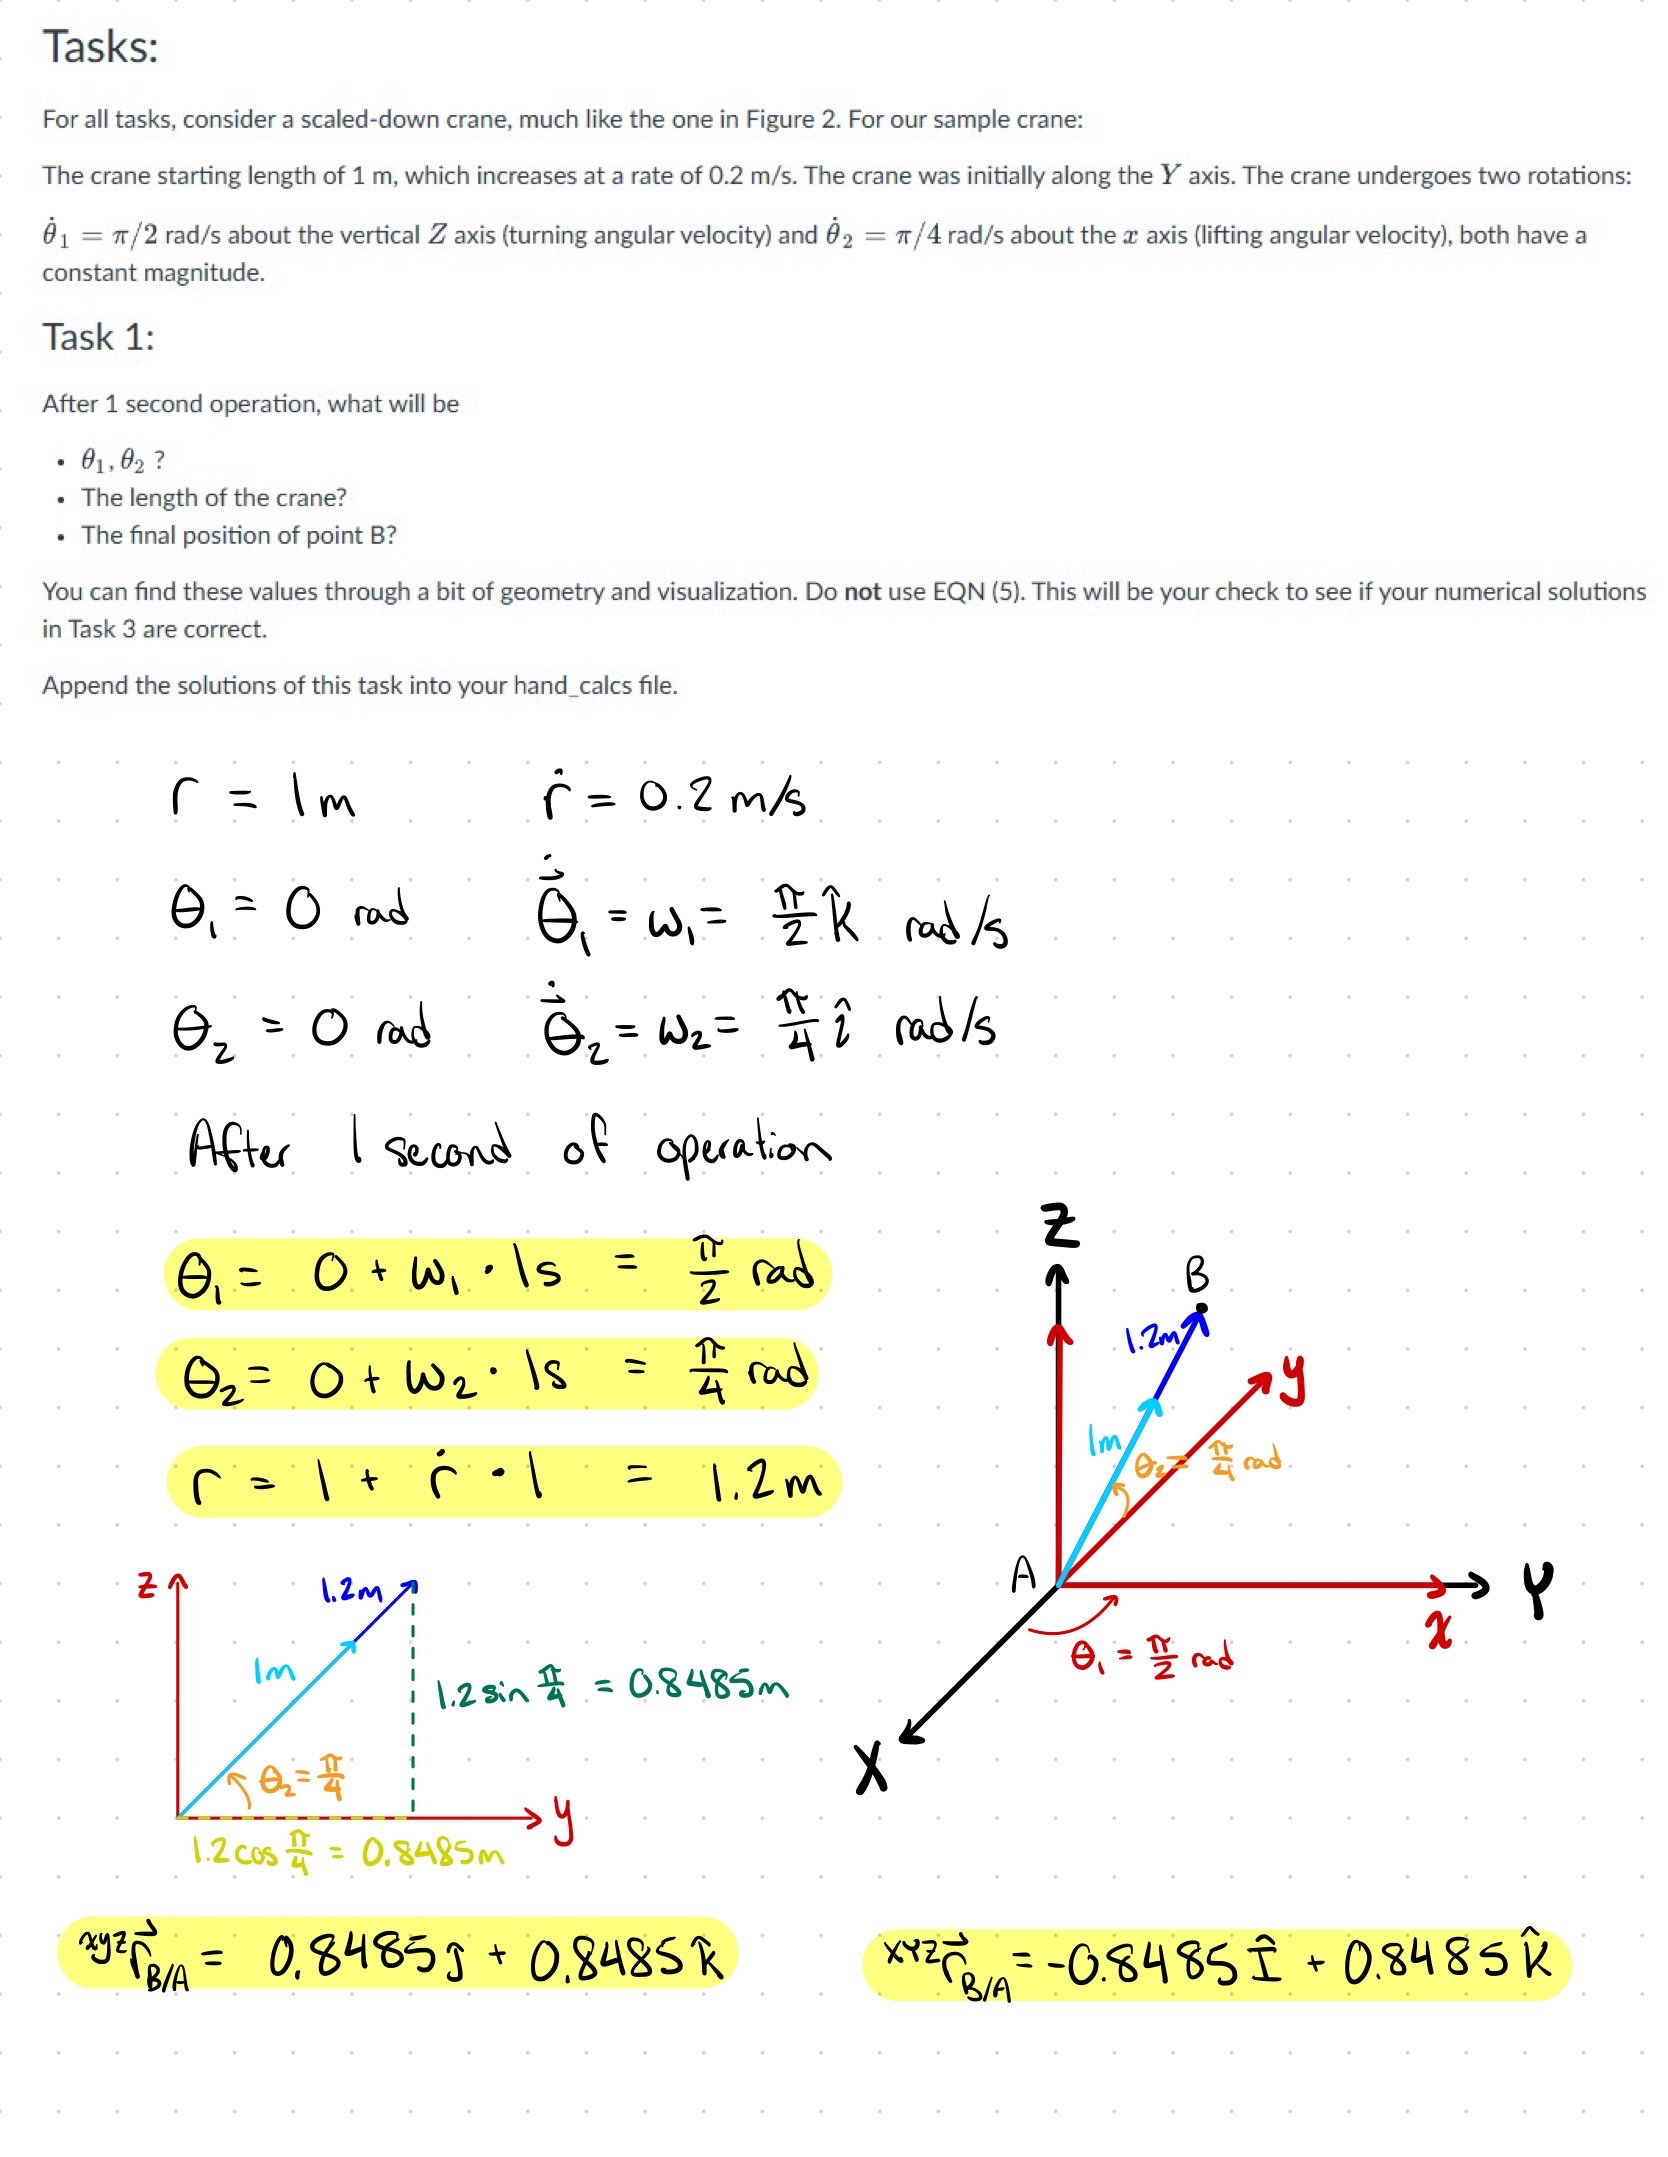

## Task 2: 

### 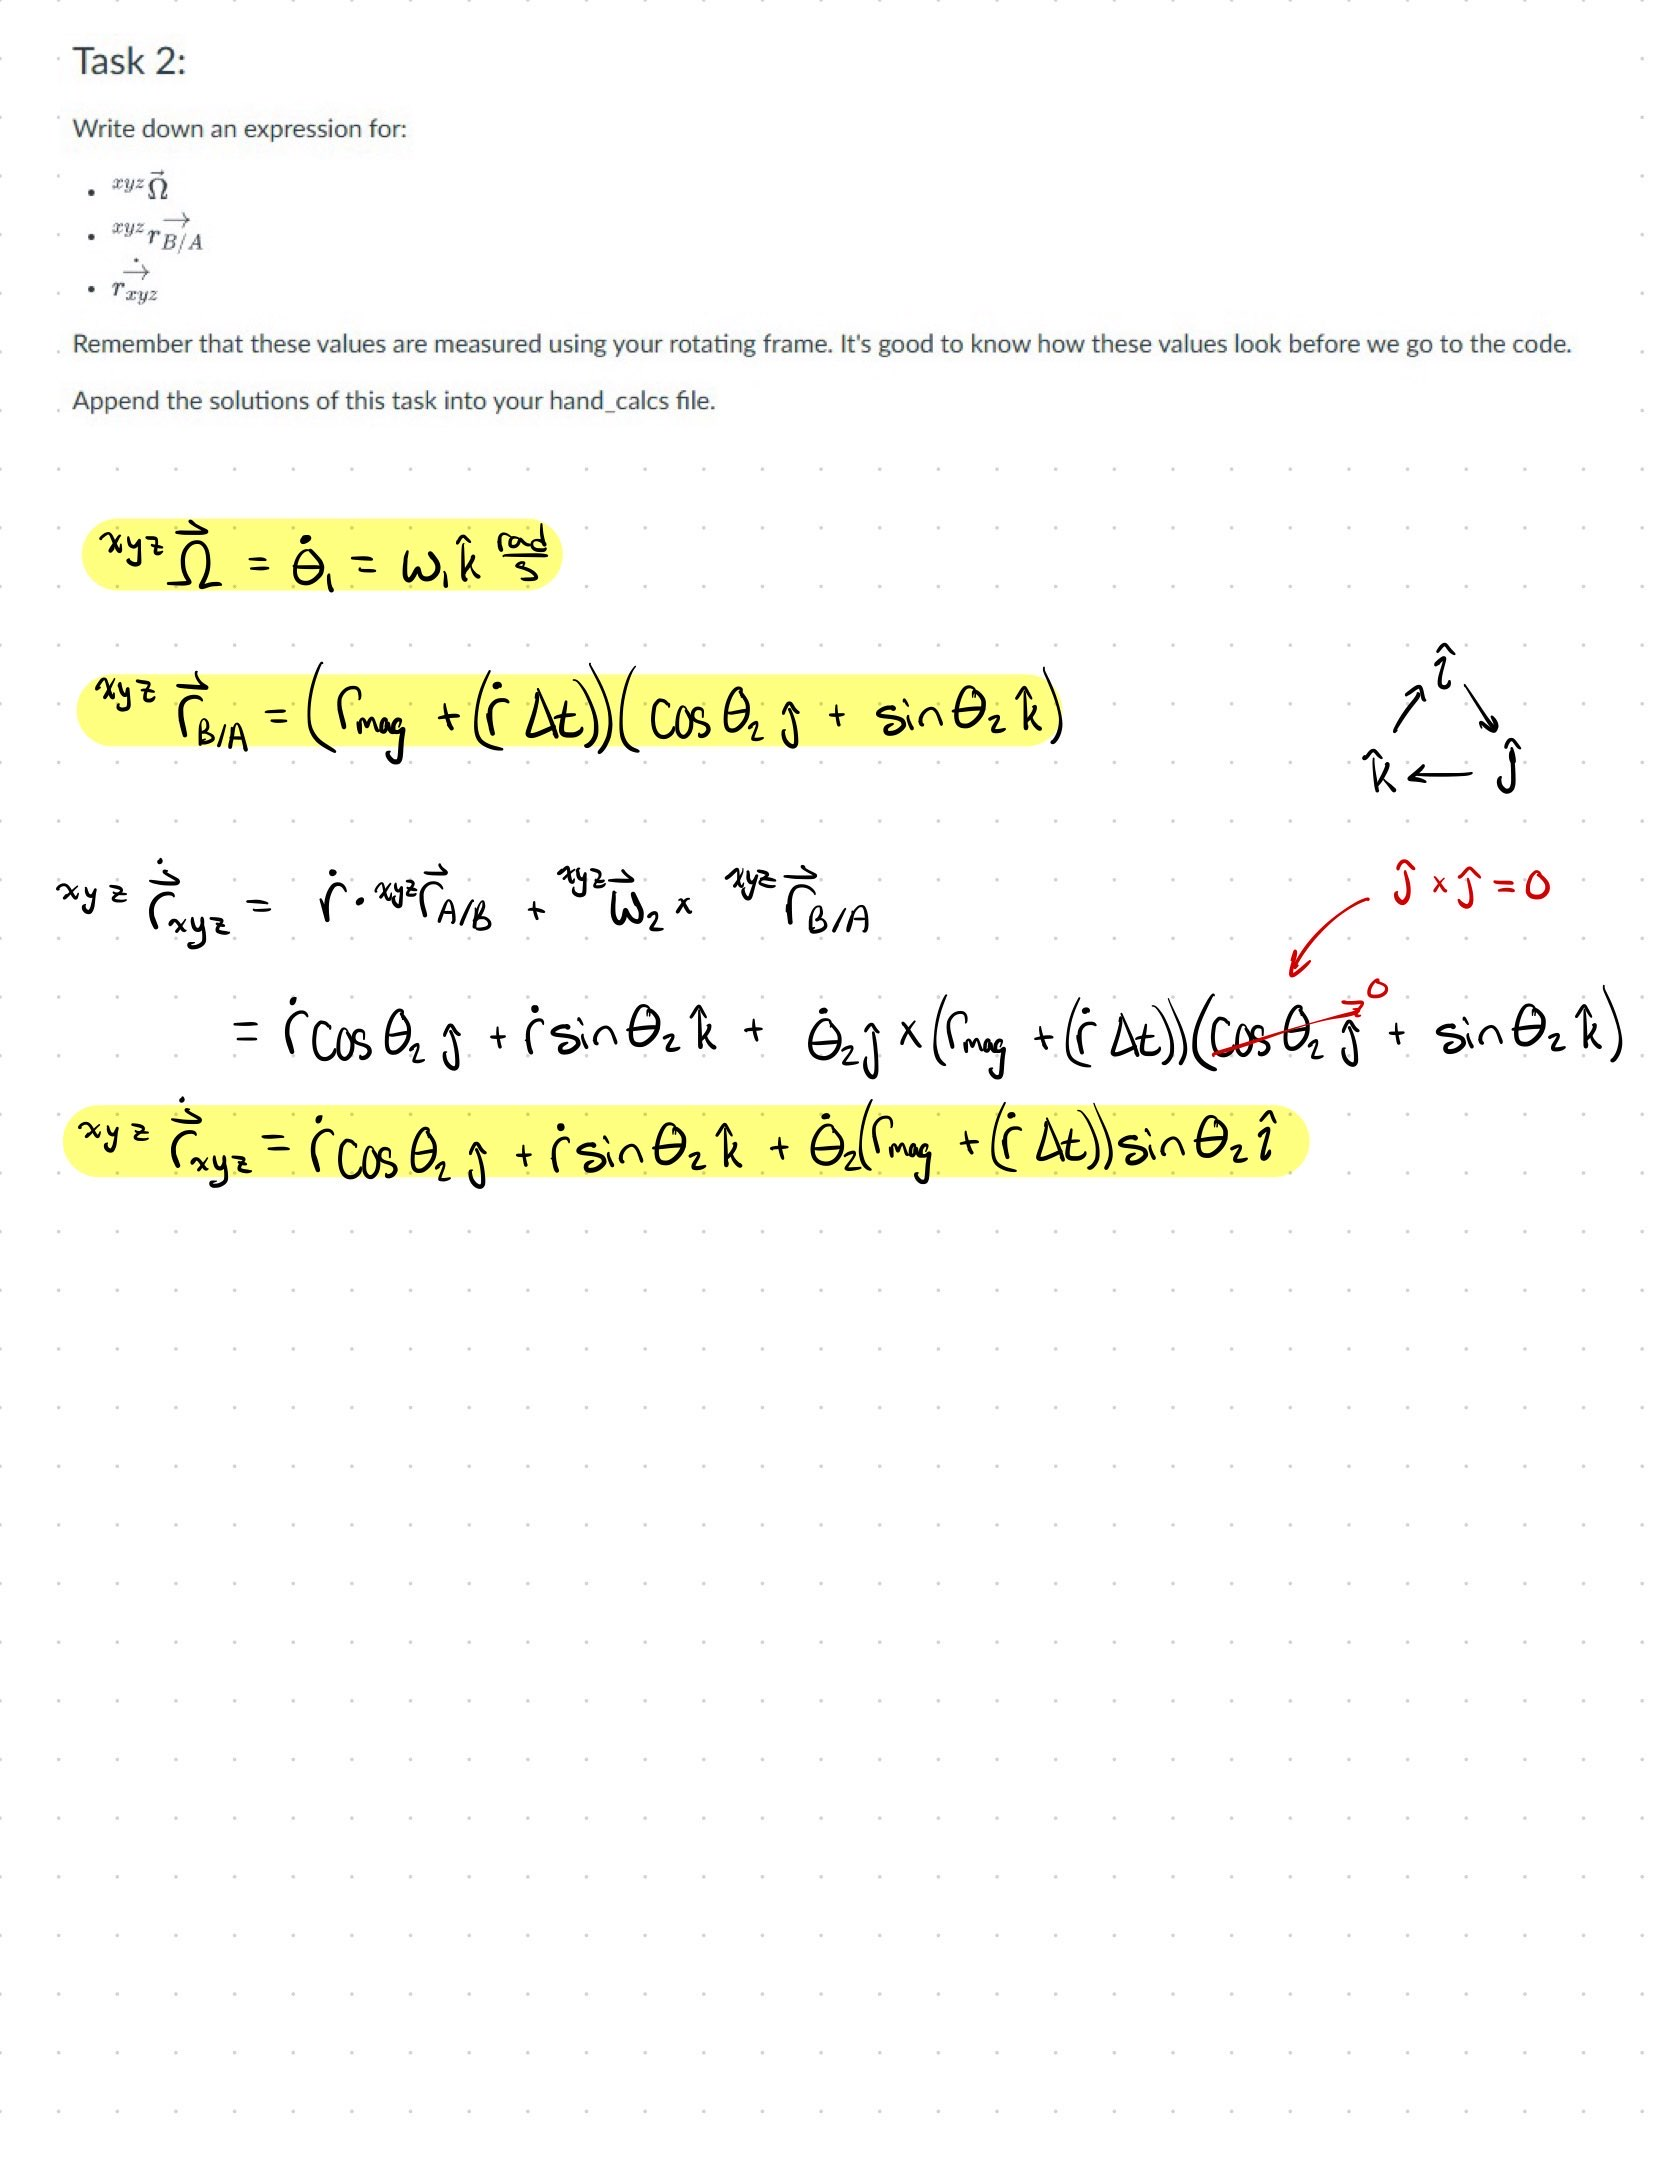

## Task 3: 

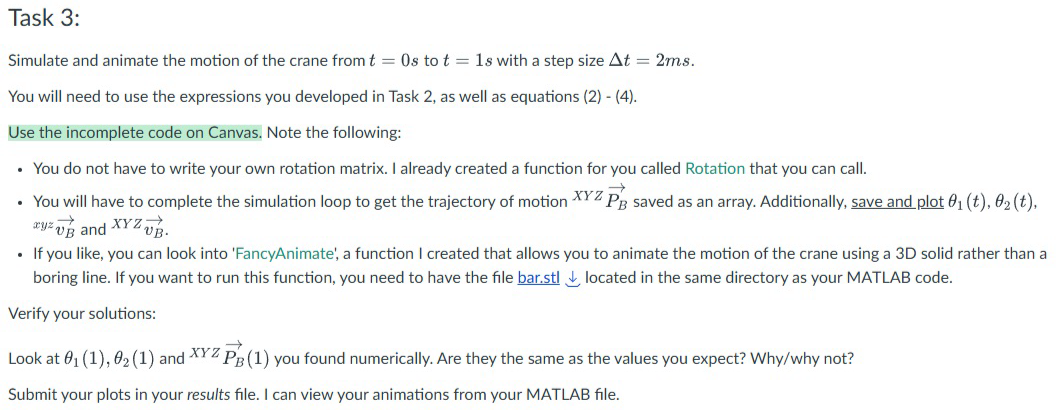

The goal of this code is to simulate and animate the motion of a scaled-down crane. The crane can undergo 2 rotations (that intersect at A) and the length of the crane changes as well.

% sample code (3D velocity kinematics)
% Note: here, I set up a rotating frame that rotates at w1 (about Z)
clear
clc

dt = 0.002; % simulation step size
t = 0:dt:1; % time vector

w1 = pi/2; % [rad/s] angular velocity magnitude about the Z axis (primary)
w2 = pi/4; % [rad/s] angular velocity magnitude about the x axis (secondary)
r_dot = 0.2; % [m/s] magnitude of velocity of crane extension outwards
w1_vec = [0; 0; w1]; % [rad/s] angular velocity theta1_dot as a vector
xyzw2_vec = [w2; 0; 0]; % [rad/s] angular velocity theta2_dot as a vector

theta1(1) = 0; % [rad] initial angle
theta2(1) = 0; % [rad] initial angle

r_mag(1) = 1; % [m] length of the crane initially

XYZr(:,1) = r_mag*[0;1;0]; % [m] Initially, the position vector r_B/A is 
% along the +Y direction
xyzr(:,1) = XYZr(:,1); % Initially the rotationald and global coordinate
% systems align 

% Simulation loop:
for i=1:length(t)
    
    R_theta2 = Rotation('x',theta2(i)); % represents the rotation due to
    % theta2 when left-multiplied to a vector
    XYZR_xyz = Rotation('z',theta1(i)); % also could be called R_theta1
    % because it represents the rotation due to theta1 when left-multiplied
    % to a vector
    
    xyzr(:,i) = (r_mag(i)*R_theta2*[0;1;0]); % extension position vector of
    % the end of the arm expressed in local xyz frame. (same as the
    % position of B in xyz frame)

    xyzrdot_xyz(:,i) = r_dot*xyzr(:,i) + cross(xyzw2_vec, xyzr(:,i)); 
    % velocity of the end of the rod due to theta2 in the xyz coordinate
    % system
    
    xyzv(:,i) = xyzrdot_xyz(:,i); 
    % velocity of the end of the rod in the xyz coordinate system
   
    XYZr(:,i) = XYZR_xyz*xyzr(:,i); % rotating the xyz coordinate
    % system rod position to the XYZ coordinates

    XYZv(:,i) = XYZR_xyz*xyzv(:,i); % rotating the xyz coordinate
    % system rod velocity to the XYZ coordinates

    % Find the next angle
    theta1(i+1) = theta1(i) + w1*dt;
    theta2(i+1) = theta2(i) + w2*dt;

    r_mag(i+1) = r_mag(i) + r_dot*dt; % calculated the length of the arm
    % over time 
end

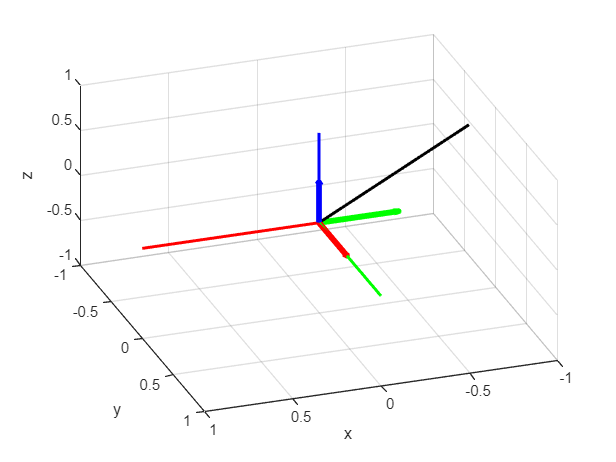

% Animate the motion (using lines)
figure(1)
animate(XYZr, theta1);

Figure 1 depicts the animated crane as it rotates about the Z axis whilst extending the beam and rotating the beam up in the j axis.

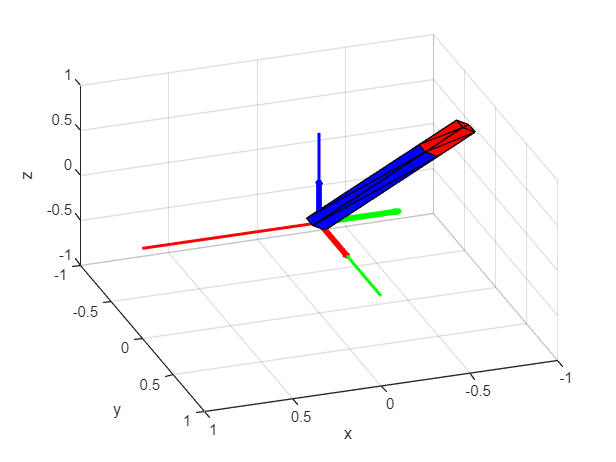

% Fancier animation using some STL files to represent the structure
% rather than lines
figure(2)
FancyAnimate(XYZr, theta1,theta2)

Figure 2 depicts the Fancy Animate version of the previously described Figure 1.

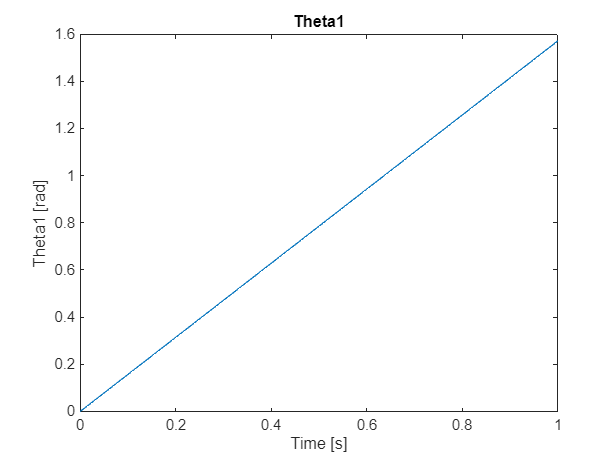

figure(3)
plot(t, theta1(1:end-1))
title('Theta1')
xlabel('Time [s]')
ylabel('Theta1 [rad]')

Figure 3 depicts the angle theta1 in radians over the time period at which the simulation is run. Theta1 changes at a constant positive rate since w1 is constant and positive.

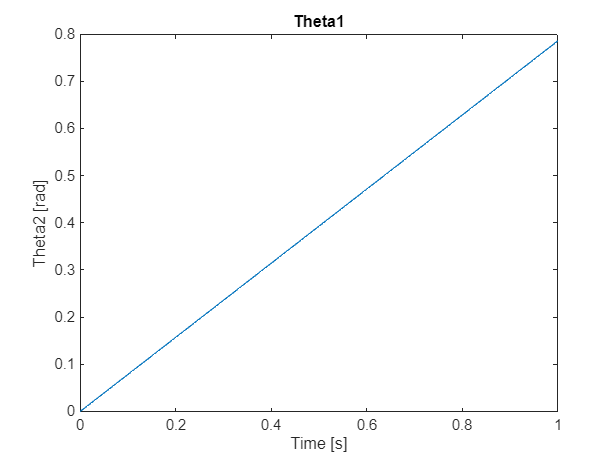

figure(4)
plot(t, theta2(1:end-1))
title('Theta1')
xlabel('Time [s]')
ylabel('Theta2 [rad]')

Figure 4 depicts the angle theta2 in radians over the time period at which the simulation is run. Theta2 changes at a constant positive rate since w2 is constant and positive.

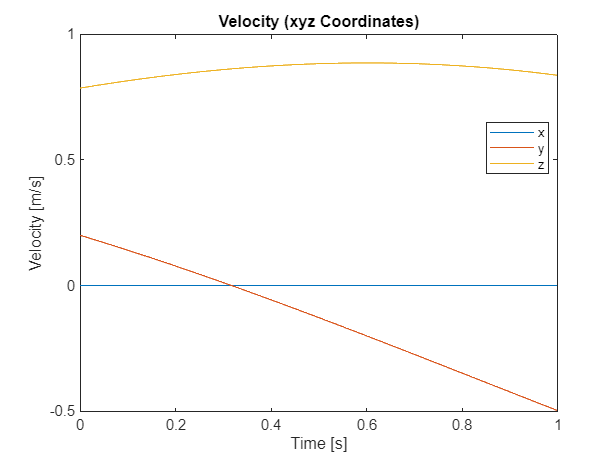

figure(5)
plot(t, xyzv(1,:), 'DisplayName', 'x') % Adding labels for legend
hold on
plot(t, xyzv(2,:), 'DisplayName', 'y') % Adding labels for legend
plot(t, xyzv(3,:), 'DisplayName', 'z') % Adding labels for legend
title('Velocity (xyz Coordinates)')
xlabel('Time [s]')
ylabel('Velocity [m/s]')
hold off
legend('Location','best');

Figure 5 depicts the velocity displayed in the xyz coordinates, this does not account for the rotation due to w1 since the coordinate system itself is rotating. This is why the velocity in the x direction is zero throughout the course of the simulation.  

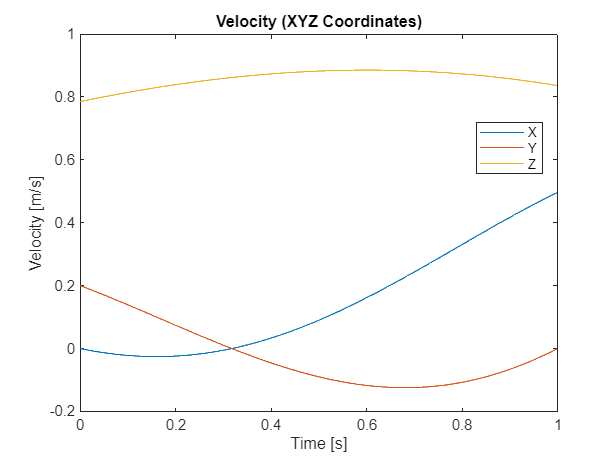

figure(6)
plot(t, XYZv(1,:), 'DisplayName', 'X') % Adding labels for legend
hold on
plot(t, XYZv(2,:), 'DisplayName', 'Y') % Adding labels for legend
plot(t, XYZv(3,:), 'DisplayName', 'Z') % Adding labels for legend
title('Velocity (XYZ Coordinates)')
xlabel('Time [s]')
ylabel('Velocity [m/s]')
hold off
legend('Location','best');

Figure 6 depicts velocity displayed in the XYZ coordinates over the course of the simulation. 

theta1(length(t))

ans = 1.5708

The expected value found in the Task 1 is: 

Theta1 = pi/2 = 1.57079

It can be noted that the values do match the precalculated values after rounding to the amount of digits given by matlab.

theta2(length(t))

ans = 0.7854

The expected value found in the Task 1 is: 

Theta2 = pi/4 = 0.78539

It can be noted that the values do match the precalculated values after rounding to the amount of digits given by matlab.

xyzr(:,length(t))

ans =          0
    0.8485
    0.8485


The expected value found in the Task 1 is: 

xyzr = 0 i_hat + 0.8485 j_hat + 0.8485 k_hat

It can be noted that the values do match the precalculated values after rounding to the amount of digits given by matlab.

XYZr(:,length(t))

ans =    -0.8485
   -0.0000
    0.8485


The expected value found in the Task 1 is: 

xyzr = -0.8485 I_hat + 0 J_hat + 0.8485 K_hat

It can be noted that the values do match the precalculated values after rounding to the amount of digits given by matlab. 

(Note there are especially rounding errors for the second term as the value is -9.36859738872830e-15 which is equivalent to 0 in this scope of this simulation).

## Functions

Below are some functions I used for convenience:

**Rotation**: Produces a rotation matrix about a chosen axis and a chosen angle.

Inputs:

- axis: a string that specifies the axis of rotation (string).

- theta: the angle of rotation about the specified axis (in rad).

**Animate**: An animation loop that produces the line plots. 

Inputs: 

- Trajectory :a 3xn matrix representing the XYZ coordinates of the end of the arm.

- theta1: a 1xn matrix representing the angle theta1 as a function of time. (used to find the orientation of the rotating frame at each instance in time).

**FancyAnimate**: Produces a fancier animation using a 3D solid rather than lines.

Note that FancyAnimate requires 'bar.stl' to be in the same directory as this matlab file.

Inputs:

- Trajectory :a 3xn matrix representing the XYZ coordinates of the end of the arm.

- theta1: a 1xn vector representing the angle theta1 as a function of time. (used to find the orientation of the rotating frame at each instance in time).

- theta2: a 1xn vector representing the angle theta2 as a function of time.

function R = Rotation(axis, theta)
    if axis == 'x' %your rotation is about the x axis
        R = [1 0 0;
             0 cos(theta) -sin(theta);
             0 sin(theta) cos(theta)];
    elseif axis == 'y' %your rotation is about the y axis
        R = [cos(theta) 0 sin(theta);
             0 1 0;
             -sin(theta) 0 cos(theta)];
    else %your rotation is about the z axis
        R = [cos(theta) -sin(theta) 0;
             sin(theta) cos(theta) 0;
             0 0 1];
    end
end

function animate(Trajectory, theta1)
    %here, trajectory is a 3xn vector
    %each row is the [X,Y,Z] position of the end of the crane
    for i=1:length(Trajectory(1,:))
        figure(1)
        plot3([0;1],[0;0],[0;0],'r',LineWidth=2)
        hold on
        plot3([0;0],[0;1],[0;0],'g',LineWidth=2)
        plot3([0;0],[0;0],[0;1],'b',LineWidth=2)
        XYZ_R_xyz = Rotation('z',theta1(i));
        %Find an expression for the x, y, z axes at this instance
        x = XYZ_R_xyz*[0.5;0;0];
        y = XYZ_R_xyz*[0;0.5;0];
        z = XYZ_R_xyz*[0;0;0.5];
        
        %plot the x y z axes using quiver:
        quiver3(0, 0, 0,  x(1), x(2), x(3), 'Color', 'red', 'LineWidth', 4);
        quiver3(0, 0, 0,  y(1), y(2), y(3), 'Color', 'green', 'LineWidth', 4);
        quiver3(0, 0, 0,  z(1), z(2), z(3), 'Color', 'blue', 'LineWidth', 4);
        
        %plot the crane as a line
        plot3([0;Trajectory(1,i)],[0;Trajectory(2,i)],[0,Trajectory(3,i)],'k',LineWidth=2)
        hold off
        xlabel 'x'
        ylabel 'y'
        zlabel 'z'

        view([160.69 40.76]);
        grid
        xlim ([-1,1])
        ylim ([-1,1])
        zlim ([-1,1])
        pause(0.01)
    end
end

function FancyAnimate(Trajectory, theta1,theta2)
    %here, trajectory is a 3xn vector
    %each row is the [X,Y,Z] position of the end of the crane

    Bar = stlread('bar.stl');
    BarPoints1 = [0.001,0.001,0.001].*Bar.Points;
    BarPoints1Starting = (Rotation('z',pi/2)*BarPoints1')';
    BarConnectivity1 = Bar.ConnectivityList;
    BarPoints2 = [0.001/9,0.001,0.001].*Bar.Points+[0.9,0,0];
    BarPoints2Starting = (Rotation('z',pi/2)*BarPoints2')';
    BarConnectivity2 = Bar.ConnectivityList;

    for i=1:length(Trajectory(1,:))
        figure(2)
        plot3([0;1],[0;0],[0;0],'r',LineWidth=2)
        hold on
        plot3([0;0],[0;1],[0;0],'g',LineWidth=2)
        plot3([0;0],[0;0],[0;1],'b',LineWidth=2)
        XYZ_R_xyz = Rotation('z',theta1(i));
        x = XYZ_R_xyz*[0.5;0;0];
        y = XYZ_R_xyz*[0;0.5;0];
        z = XYZ_R_xyz*[0;0;0.5];
        quiver3(0, 0, 0,  x(1), x(2), x(3), 'Color', 'red', 'LineWidth', 4);
        quiver3(0, 0, 0,  y(1), y(2), y(3), 'Color', 'green', 'LineWidth', 4);
        quiver3(0, 0, 0,  z(1), z(2), z(3), 'Color', 'blue', 'LineWidth', 4);

        R = Rotation('z',theta1(i))*Rotation('x',theta2(i));
        BarPoints1 = (R*BarPoints1Starting')';
        BarPoints2 = [0.001/9*(norm(Trajectory(:,i))-0.9)/0.1,0.001,0.001].*Bar.Points+[0.9,0,0];
        BarPoints2Starting = (Rotation('z',pi/2)*BarPoints2')';
        BarPoints2 = (R*BarPoints2Starting')';
        trimesh(BarConnectivity1,BarPoints1(:,1),BarPoints1(:,2),BarPoints1(:,3),'edgecolor','k','facecolor','b')
        trimesh(BarConnectivity2,BarPoints2(:,1),BarPoints2(:,2),BarPoints2(:,3),'edgecolor','k','facecolor','r')

        hold off
        xlabel 'x'
        ylabel 'y'
        zlabel 'z'
        %view([150,30]);
        view([160.69 40.76]);
        grid
        xlim ([-1,1])
        ylim ([-1,1])
        zlim ([-1,1])
        pause(0.1)
    end
end